## Env

clc,clear all

addpath('E:/JHU/Research/QSM/JHUKKI_QSM_Toolbox_v3.3.1/QSM_Utility/masking');
addpath('E:/JHU/Research/QSM/JHUKKI_QSM_Toolbox_v3.3.1/QSM_NIFTI/');
addpath('E:/52594/OneDrive - Johns Hopkins/Research/Orig/Lin_example/imtool3D_td-master');
addpath('E:/UKB');
addpath('E:/UKB/SynthSegMatlab/SynthSeg/');

pathname_main = 'E:/UKB';
fin_datasetfolder = 'E:/UKB/othermodality/input';
in_filePattern = fullfile(fin_datasetfolder, '*.nii.gz');
in_T1Files = dir(in_filePattern);
ndata_in = length(in_T1Files);

cd(fin_datasetfolder);
for idata=1:ndata_in
  
    modalityname = in_T1Files(idata).name;
    cd(in_T1Files(idata).folder)
    
    % casename = modalityname(1:end-10);
    if exist(modalityname,"file")
        h = niftiinfo(modalityname);
        if contains(modalityname,'.gz')
            f_input_t = strrep(modalityname,'.nii.gz','_1mmIntp.nii');
        else
            f_input_t = strrep(modalityname,'.nii','_1mmIntp.nii');
        end

        % fullfilepath = fullfile(f_input_t); %for command line model running

        img_t = niftiread(modalityname);
        voxel_t = h.PixelDimensions;
        size_t = h.ImageSize;

        % Calculate new dimensions as shown in the previous explanation
        % Adjust for actual voxel size from metadata
        newHeight = size(img_t, 1) * (voxel_t(1) / 1); % Assuming 1 mm is the desired voxel size
        newWidth = size(img_t, 2) * (voxel_t(2) / 1);
        newDepth = size(img_t, 3) * (voxel_t(3) / 1);

        % Round the calculated dimensions as imresize3 expects integer values
        newDimensions = round([newHeight, newWidth, newDepth]);

        % Resample the image
        resampledImg = imresize3(img_t, newDimensions, 'linear');

        % if prod(mod(size_t,32)==0)~=1 % dim is not multiples of 32
        %     pad_size = mod(size_t,2); % add dim is not even number
        %     pad_size = pad_size + mod(32-mod(size_t+pad_size,32),32);
        %     img_t = padarray(img_t,pad_size,0,'post');
        % else
        %     pad_size = [0 0 0];
        % end

        ht = h;
        ht.PixelDimensions(:) = 1.0;
        ht.ImageSize= size(resampledImg);
        cd("1mmIntp\")
        % niftiwrite(img_t,f_input_t ,ht)
        niftiwrite(resampledImg, f_input_t, ht);

        ht = niftiinfo(f_input_t);
        if prod(ht.PixelDimensions == [1 1 1])~=1 % non 1mm isotropic
            error('Final interpolated image resolution is not [1 1 1] ')
        end

    end 
end 


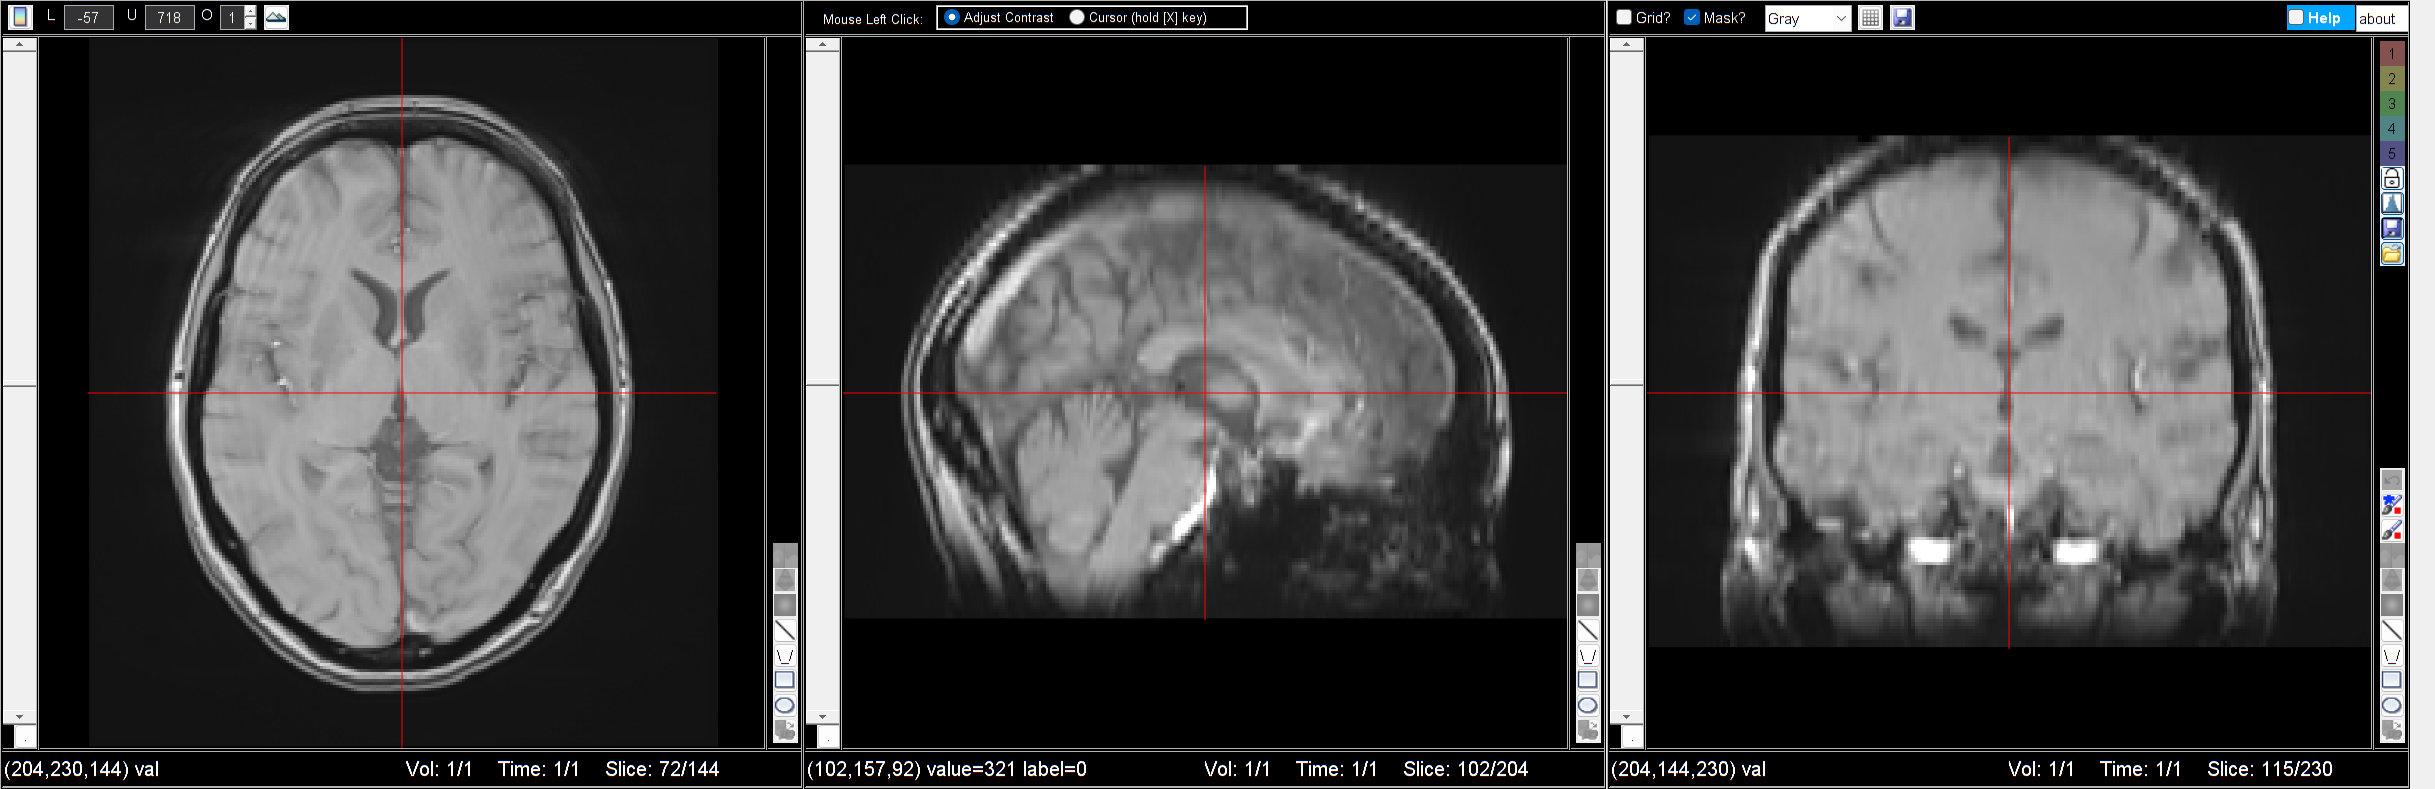

tool = imtool3D_3planes({resampledImg});
tool.setNvol(2); 

pathname_main = 'E:/UKB';
fin_datasetfolder = 'E:/UKB/othermodality/input';
in_filePattern = fullfile(fin_datasetfolder,'*.nii.gz');
in_T1Files = dir(in_filePattern);
ndata_in = length(in_T1Files);

outputdir = 'E:/UKB/othermodality/output';
SynthSegdir = 'D:/GitHub/SynthSeg';
flag_delete_intermediatefiles = 0;
flag_save_brain_mask = 1;

cd(fin_datasetfolder);
for idata=1:ndata_in
    foldername = in_T1Files(idata).folder;
    modalityname = in_T1Files(idata).name;
    casename = strrep(modalityname,'.nii.gz','');
    disp(['For',casename])
    modalityname = fullfile(foldername,'\',modalityname);
    modality_1mmIntp_name = fullfile(foldername,'\1mmIntp\',in_T1Files(idata).name);
    h = niftiinfo(modalityname);
    img_t = niftiread(modalityname);

    % Original voxel sizes from the niftiinfo of the original image
    voxelSize = h.PixelDimensions;
    

    % Original image dimensions
    originalDimensions = [size(img_t, 1), size(img_t, 2), size(img_t, 3)];


    if contains(modality_1mmIntp_name,'.gz')
        f_input_t = strrep(modality_1mmIntp_name,'.nii.gz','_1mmIntp.nii');
    else
        f_input_t = strrep(modality_1mmIntp_name,'.nii','_1mmIntp.nii');
    end

    ht = niftiinfo(f_input_t);

    seg_name = strcat(casename, '_synthseg.nii');
    seg_name = fullfile(outputdir,'/',seg_name);

    seg_1mmIntp_name = strcat(casename, '_1mmIntp_synthseg.nii');
    seg_1mmIntp_name = fullfile(outputdir,'/',seg_1mmIntp_name);
    h_out =niftiinfo(seg_1mmIntp_name);
    img_out = niftiread(seg_1mmIntp_name);

    % method 1 to Create a mapping to 0-99
    unique_labels = unique(img_out);  % Get all unique labels
    label_map = containers.Map(unique_labels, 0:length(unique_labels)-1);  
    % Apply mapping to the image
    for label = unique_labels'
        img_out(img_out == label) = label_map(label);
    end

    % Resize the segmented image back to the original dimensions
    segmentedOriginalSpace = imresize3(img_out, originalDimensions, 'Method', 'nearest');


    % Use the original NIfTI header but update the data type and dimensions as needed
    segmentedHeader = h; % Copy the original header
    % segmentedHeader.Datatype = class(segmentedOriginalSpace); % Update the data type based on the segmentation mask
    % segmentedHeader.ImageSize = size(segmentedOriginalSpace); % Update the dimensions
    segmentedHeader.Datatype = 'uint8';

    mask = uint8(imdilate(segmentedOriginalSpace>0,strel('sphere',1)));
    
    img_ori = niftiread(modalityname);
    img_ori(~mask) = 0;

    mask_path = strrep(seg_name,'.nii','_brain_mask.nii');
    brain_path = strrep(seg_name,'.nii','_brain.nii');
    
    if flag_delete_intermediatefiles == 1 %delete files not in original space
        delete(f_input_t)
        delete(seg_1mmIntp_name)
    end 

    

    
    segmentedOriginalSpace = uint8(segmentedOriginalSpace);
    % niftiwrite(segmentedOriginalSpace,seg_name,h,'compressed',0)
    niftiwrite(segmentedOriginalSpace, seg_name, segmentedHeader, 'Compressed', 0);
    disp('Seg in Nifti saved');
    save_NII = extractBefore(seg_name, '.nii');
    saveNII_Name = [save_NII,'.img'];
    struMapData = make_nii(segmentedOriginalSpace,segmentedHeader.PixelDimensions);
    save_nii(struMapData,saveNII_Name);
    disp('Seg in analysis format saved');
    % output_path.seg = seg_name;

    %brain mask
    if flag_save_brain_mask ==1
        niftiwrite(mask,mask_path,segmentedHeader,'compressed',0)
        disp('mask in Nifti saved');
        niftiwrite(img_ori,brain_path ,niftiinfo(modalityname),'compressed',0)
        disp('brain in Nifti saved');
        % output_path.bmask = mask_path;
        % output_path.brain = brain_path;
    end

    % output.seg = niftiread(fn_out);
    % output.input = niftiread(fn_input);

end 

ForQSM_mcpc3Ds_MAG_TE1


Seg in Nifti saved


Seg in analysis format saved


mask in Nifti saved


brain in Nifti saved


ForSOS_TE1


Seg in Nifti saved


Seg in analysis format saved


mask in Nifti saved


brain in Nifti saved


ForSOS_TE2


Seg in Nifti saved


Seg in analysis format saved


mask in Nifti saved


brain in Nifti saved


ForSWI


Seg in Nifti saved


Seg in analysis format saved


mask in Nifti saved


brain in Nifti saved


ForSWI_TOTAL_MAG


Seg in Nifti saved


Seg in analysis format saved


mask in Nifti saved


brain in Nifti saved
